# **Exploring brain-behaviour relationships in the tbfMRI choir-singing dataset**

The results from the linguistic analyses are:

- UU INT (Group AB TP2-1) & TY INT (Group BA TP3-2)(syllables, syllables errors, perc)

- UU-TY INT (Group AB) & TY-UU INT (Group BA)

clear all
% Specify directories and patients
data_path='/Users/noeliamartinezmolina/Documents/Aphasia_project/tb-fMRI/results/post-pre_diff_images/TU/';
output_path='/Users/noeliamartinezmolina/Documents/Aphasia_project/tb-fMRI/results/syllables/cluster/all';
syll_path='/Users/noeliamartinezmolina/Documents/Aphasia_project/tb-fMRI/results/syllables/';
mask_path='/Users/noeliamartinezmolina/Documents/Aphasia_project/tb-fMRI/results/'

mask_path = '/Users/noeliamartinezmolina/Documents/Aphasia_project/tb-fMRI/results/'

code_path='/Users/noeliamartinezmolina/Documents/GitHub/tbfMRI_LASA_current_code/notebooks/syllables'; 
addpath(code_path)

First, we will extract the values from the significant behavioural variables for each patient:

% Import behavioural data and extract variables for the fMRI sample
import_syllables(fullfile(syll_path,'LASA_UULAATYDYY_fMRI_N19.csv'));
UUTYsyll_int_all=ans.UU_TY_syllable_sum_INT;
UUTYsyllerrors_int_all=ans.UU_TY_syllable_sum_syllables_errors_INT;
UUTYsyllperc_int_all=ans.UU_TY_syllable_sum_percent_INT;
XXminusYYsyllperc_int_all=ans.XX_minus_YY_syll_sum_perc_INT;
ID_BIDS_all=ans.ID_BIDS;

Second, we will extract the average intensity values from the clusters with significant results in the paired T-test and flexible factorial for the corresponding contrasts (peak value of the cluster below):

- Paired T, Tydyy-Uulaa Singing along vs rest: PoG R (48,-16,39)

- Paired T, Tydyy-Uulaa Singing along vs singing from memory: PreG R/IFG R (58,4,29)

- Flexible ABvsBA&TP2vsTP1, Tydyy-Uulaa Singing along vs rest: STG R (48,-12,15)

% Save peak value and contrast name to variable
peak1=[48,-16,39];% paired T singavsrest MNI coord in mm from the cluster
peak2=[58,4,29]; %paired T singavssingm MNI coord in mm from the cluster
peak3=[48,-12,15]; %flexible singavsrest MNI coord in mm from the cluster
contrast1='Sing_along>Baseline';
contrast2='Sing_along>Sing_mem';
mask1name='singavsrest_T_clus48-1639.nii';
mask2name='singvsrest_flex_clus48-12-5.nii';
mask3name='singavssingm_T_clus58429.nii';



## Contrast 1: Paired T test Tydyy-Uulaa Sing along vs Rest

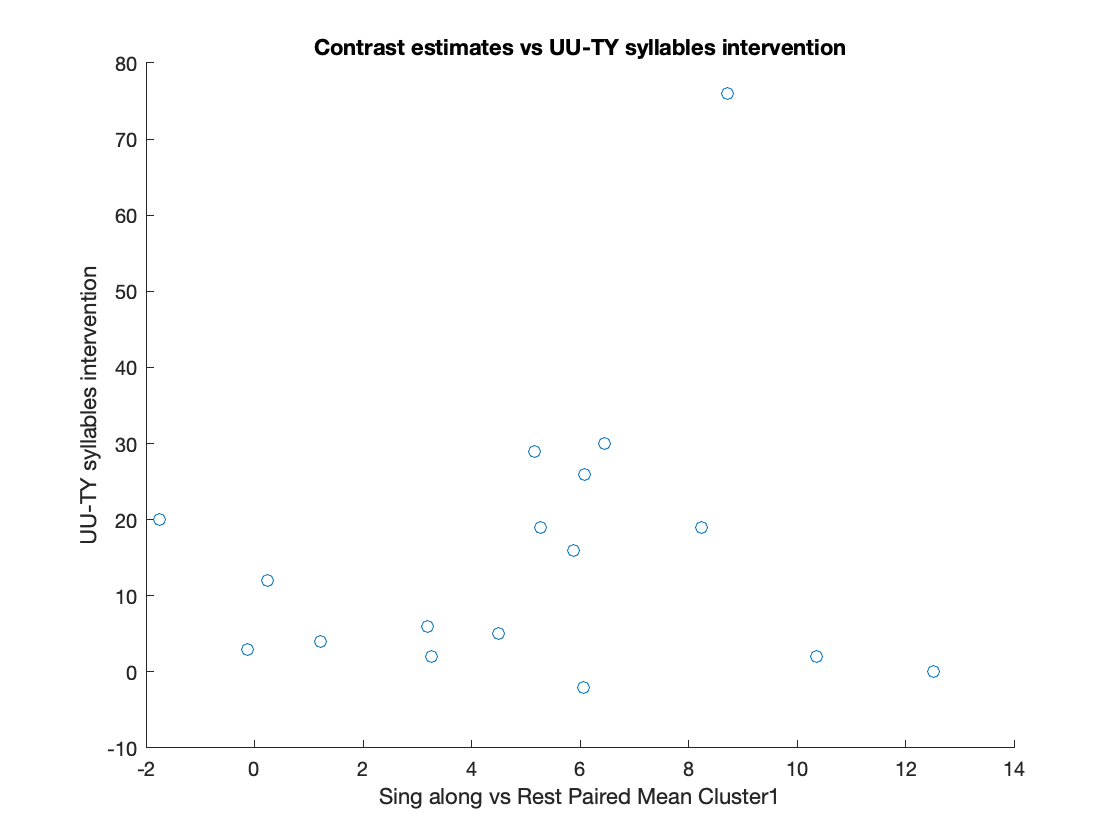

% Get the image filenames
filenames_contrast1= dir(fullfile(data_path,contrast1));
filenames_contrast1(ismember({filenames_contrast1.name},{'.','..'}))=[];

% Get L2 mask indices from FWEc cluster
    mask1=spm_vol(fullfile(mask_path,'paired T test/singa_vs_rest_TU_Age_TIV_wo_motion_outliers_wo_14/',mask1name)); %created manually with SPM L2 results
    [M, XYZmm]=spm_read_vols(mask1);
    mask1_idx=find(M~=0);
    mask1_int=mean(M(mask1_idx));%internal check
    
% Get mean cluster intensity for all patients
for i=1:size(filenames_contrast1,1)
    V=spm_vol(fullfile(data_path,contrast1,filenames_contrast1(i).name)); % Get image information
    [Y, XYZmm]=spm_read_vols(V);
    mean_int=mean(Y(mask1_idx));
    [~,name,ext] =fileparts(filenames_contrast1(i).name);
    pa_int_mask1{i,1}=str2num(name(end-1:end)); %Save the patient ID in BIDS
    pa_int_mask1{i,2}=mean_int;% Save mean intensity value for the cluster from all patients
end

%% Get behavioural values from the patients with existing images
ID_BIDS_pat=cell2mat(pa_int_mask1(:,1));
[idx_pat,iall,i] = intersect(ID_BIDS_all,ID_BIDS_pat);
UUTYsyll_int_pat_contrast1=UUTYsyll_int_all(iall,:);
UUTYsyllerrors_int_pat_contrast1=UUTYsyllerrors_int_all(iall,:);
UUTYsyllperc_int_pat_contrast1=UUTYsyllperc_int_all(iall,:);
XXminusYYsyllperc_int_pat_contrast1=XXminusYYsyllperc_int_all(iall,:);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% BEHAVIORAL VARIABLE #1 %%%
% Remove patients with NaN values in behaviour
if sum(isnan(UUTYsyll_int_pat_contrast1(:,1)))~=0
    NAN_Index_contrast1=find(isnan(UUTYsyll_int_pat_contrast1(:,1)));
    UUTYsyll_int_pat_contrast1(NAN_Index_contrast1,:)=[];
    pa_int_mask1_UUTYsyll=cell2mat(pa_int_mask1(:,2));
    pa_int_mask1_UUTYsyll(NAN_Index_contrast1,:)=[];
end

%% Plot Intensity against behaviour for the cluster mean
for p=1:size(1,1)
        y=UUTYsyll_int_pat_contrast1;
        if exist('pa_int_mask1_UUTYsyll')==1
            x=pa_int_mask1_UUTYsyll;
        else
            x=cell2mat(pa_int_mask1(:,2))
        end
        figure
        scatter(x,y)
        title ('Contrast estimates vs UU-TY syllables intervention'), xlabel(['Sing along vs Rest Paired Mean Cluster' num2str(p)]), ylabel ('UU-TY syllables intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_PairedT_SingavsRest_UUTY_syll_int_T_mean_cluster' num2str(p) '.jpg'])
        save('UUTY_syll_int_singavsrest_mean_cluster','x','y')
        UUTYsyllint_singavsrest_T=table(x,y);
        writetable(UUTYsyllint_singavsrest_T, 'UUTYsyllint_singavsrest_T_mean_cluster.xlsx')
end


% correlation
[rho_mask1,pval_mask1] = corr(x,y,'Type','Pearson')

rho_mask1 = 0.1800

pval_mask1 = 0.4893

[rho_mask1,pval_mask1] = corr(x,y,'Type','Spearman')

rho_mask1 = 0.0577

pval_mask1 = 0.8260

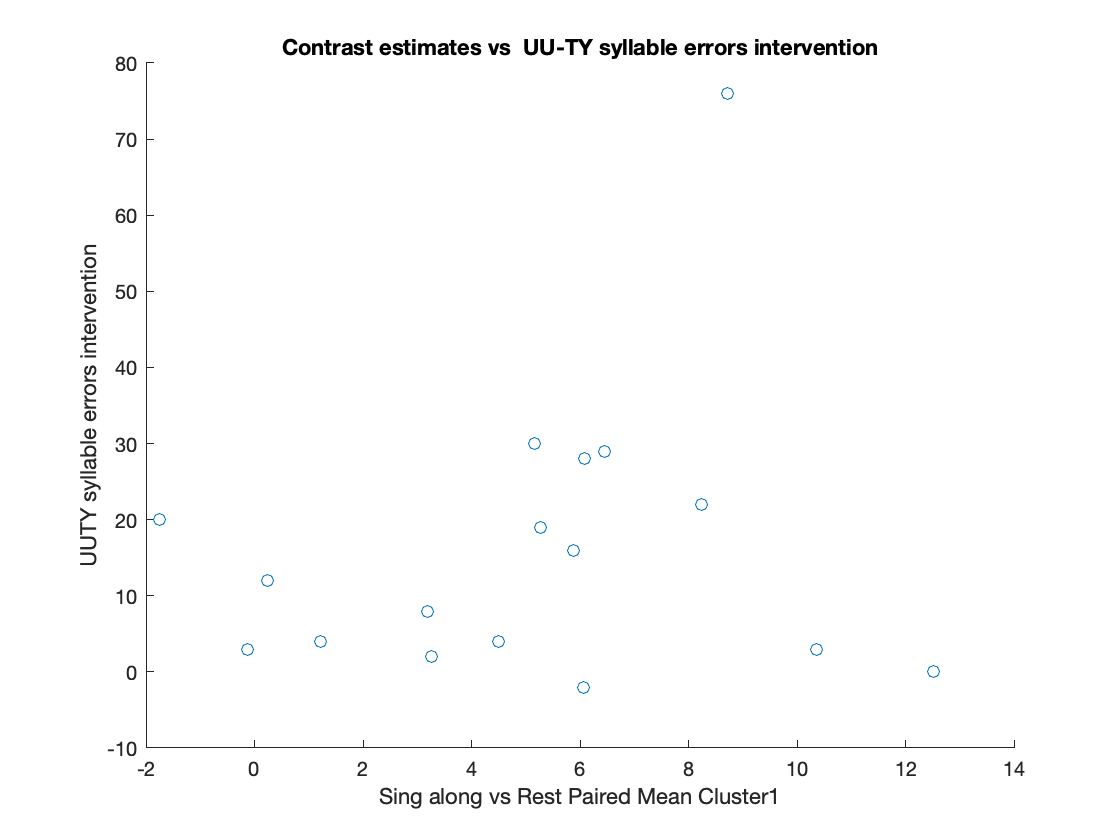

clear x y
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% BEHAVIORAL VARIABLE #2 %%%
% Remove patients with NaN values in behaviour
if sum(isnan(UUTYsyllerrors_int_pat_contrast1(:,1)))~=0
    NAN_Index_contrast1=find(isnan(UUTYsyllerrors_int_pat_contrast1(:,1)));
    UUTYsyllerrors_int_pat_contrast1(NAN_Index_contrast1,:)=[];
    pa_int_mask1_UUTYsyllerrors=cell2mat(pa_int_mask1(:,2));
    pa_int_mask1_UUTYsyllerrors(NAN_Index_contrast1,:)=[];
end

%% Plot Intensity against behaviour for the cluster mean
for p=1:size(mask1,1)
        y=UUTYsyllerrors_int_pat_contrast1;
           if exist('pa_int_mask1_UUTYsyllerrors')==1
            x=pa_int_mask1_UUTYsyllerrors;
        else
            x=cell2mat(pa_int_mask1(:,2))
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs  UU-TY syllable errors intervention'), xlabel(['Sing along vs Rest Paired Mean Cluster' num2str(p)]), ylabel ('UUTY syllable errors intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_PairedT_SingavsRest_UUTY_syllable_errors_int_T_mean_cluster' num2str(p) '.jpg'])
        save('UUTY_syll_errors_int_singavsrest_mean_cluster','x','y')
        UUTYsyllerrorsint_singavsrest_T=table(x,y);
        writetable(UUTYsyllerrorsint_singavsrest_T, 'UUTYsyllerrorsint_singavsrest_T_mean_cluster.xlsx')
end


% correlation
[rho_mask1,pval_mask1] = corr(x,y,'Type','Pearson')

rho_mask1 = 0.1907

pval_mask1 = 0.4635

[rho_mask1,pval_mask1] = corr(x,y,'Type','Spearman')

rho_mask1 = 0.1092

pval_mask1 = 0.6765

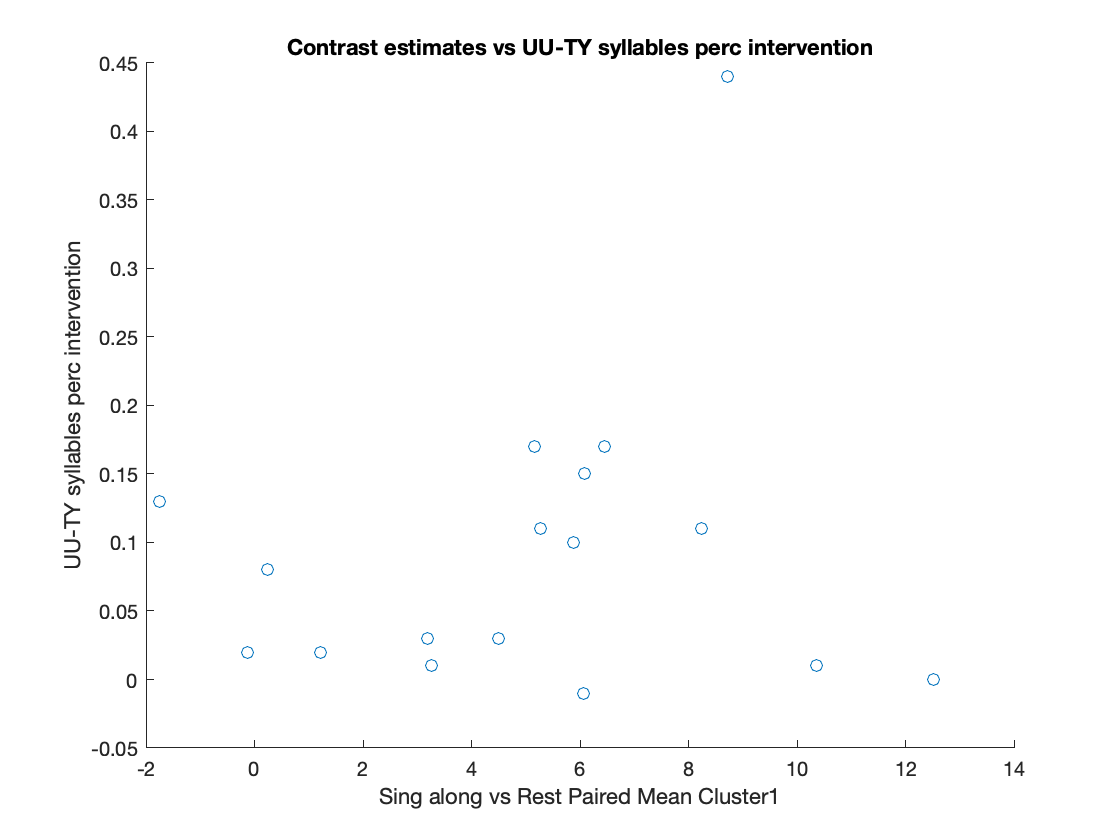

clear x y M mean_int Y V

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% BEHAVIORAL VARIABLE #3 %%%
% Remove patients with NaN values in behaviour
if sum(isnan(UUTYsyllperc_int_pat_contrast1(:,1)))~=0
    NAN_Index_contrast1=find(isnan(UUTYsyllperc_int_pat_contrast1(:,1)));
    UUTYsyllperc_int_pat_contrast1(NAN_Index_contrast1,:)=[];
    pa_int_mask1_UUTYsyllperc=cell2mat(pa_int_mask1(:,2));
    pa_int_mask1_UUTYsyllperc(NAN_Index_contrast1,:)=[];
end

%% Plot Intensity against behaviour for the cluster mean
for p=1:size(1,1)
        y=UUTYsyllperc_int_pat_contrast1;
        if exist('pa_int_mask1_UUTYsyllperc')==1
            x=pa_int_mask1_UUTYsyllperc;
        else
            x=cell2mat(pa_int_mask1(:,2))
        end
        figure
        scatter(x,y)
        title ('Contrast estimates vs UU-TY syllables perc intervention'), xlabel(['Sing along vs Rest Paired Mean Cluster' num2str(p)]), ylabel ('UU-TY syllables perc intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_PairedT_SingavsRest_UUTY_syll_perc_int_T_mean_cluster' num2str(p) '.jpg'])
        save('UUTY_syll_perc_int_singavsrest_mean_cluster','x','y')
        UUTYsyllpercint_singavsrest_T=table(x,y);
        writetable(UUTYsyllpercint_singavsrest_T, 'UUTYsyllpercint_singavsrest_T_mean_cluster.xlsx')
end


% correlation
[rho_mask1,pval_mask1] = corr(x,y,'Type','Pearson')

rho_mask1 = 0.1579

pval_mask1 = 0.5449

[rho_mask1,pval_mask1] = corr(x,y,'Type','Spearman')

rho_mask1 = 0.0516

pval_mask1 = 0.8440

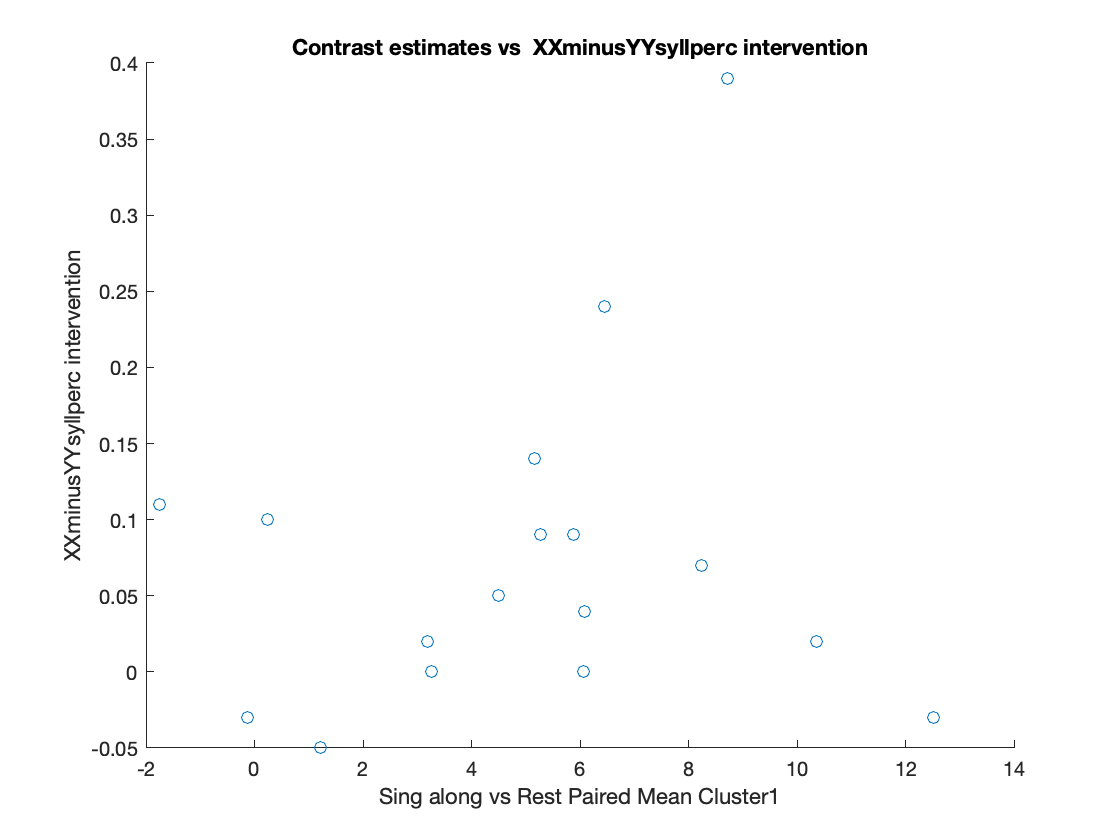

clear x y

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% BEHAVIORAL VARIABLE #4 %%%
% Remove patients with NaN values in behaviour
if sum(isnan(XXminusYYsyllperc_int_pat_contrast1(:,1)))~=0
    NAN_Index_contrast1=find(isnan(XXminusYYsyllperc_int_pat_contrast1(:,1)));
    XXminusYYsyllperc_int_pat_contrast1(NAN_Index_contrast1,:)=[];
    pa_int_mask1_XXminusYYsyllperc=cell2mat(pa_int_mask1(:,2));
    pa_int_mask1_XXminusYYsyllperc(NAN_Index_contrast1,:)=[];
end

%% Plot Intensity against behaviour for the cluster mean
for p=1:size(mask1,1)
        y=XXminusYYsyllperc_int_pat_contrast1;
           if exist('pa_int_mask1_XXminusYYsyllperc')==1
            x=pa_int_mask1_XXminusYYsyllperc;
        else
            x=cell2mat(pa_int_mask1(:,2))
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs  XXminusYYsyllperc intervention'), xlabel(['Sing along vs Rest Paired Mean Cluster' num2str(p)]), ylabel ('XXminusYYsyllperc intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_PairedT_SingavsRest_XXminusYYsyllperc_int_T_mean_cluster' num2str(p) '.jpg'])
        save('XXminusYYsyllpercint_singavsrest_mean_cluster','x','y')
        XXminusYYsyllpercint_singavsrest_T=table(x,y);
        writetable(XXminusYYsyllpercint_singavsrest_T, 'XXminusYYsyllpercint_singavsrest_T_mean_cluster.xlsx')
end


% correlation
[rho_mask1,pval_mask1] = corr(x,y,'Type','Pearson')

rho_mask1 = 0.1695

pval_mask1 = 0.5155

[rho_mask1,pval_mask1] = corr(x,y,'Type','Spearman')

rho_mask1 = 0.1007

pval_mask1 = 0.7005

clear x y M mean_int Y V


## Contrast 1: Flexible AB>BAxTP2>TP1 Tydyy-Uulaa Sing along vs Rest

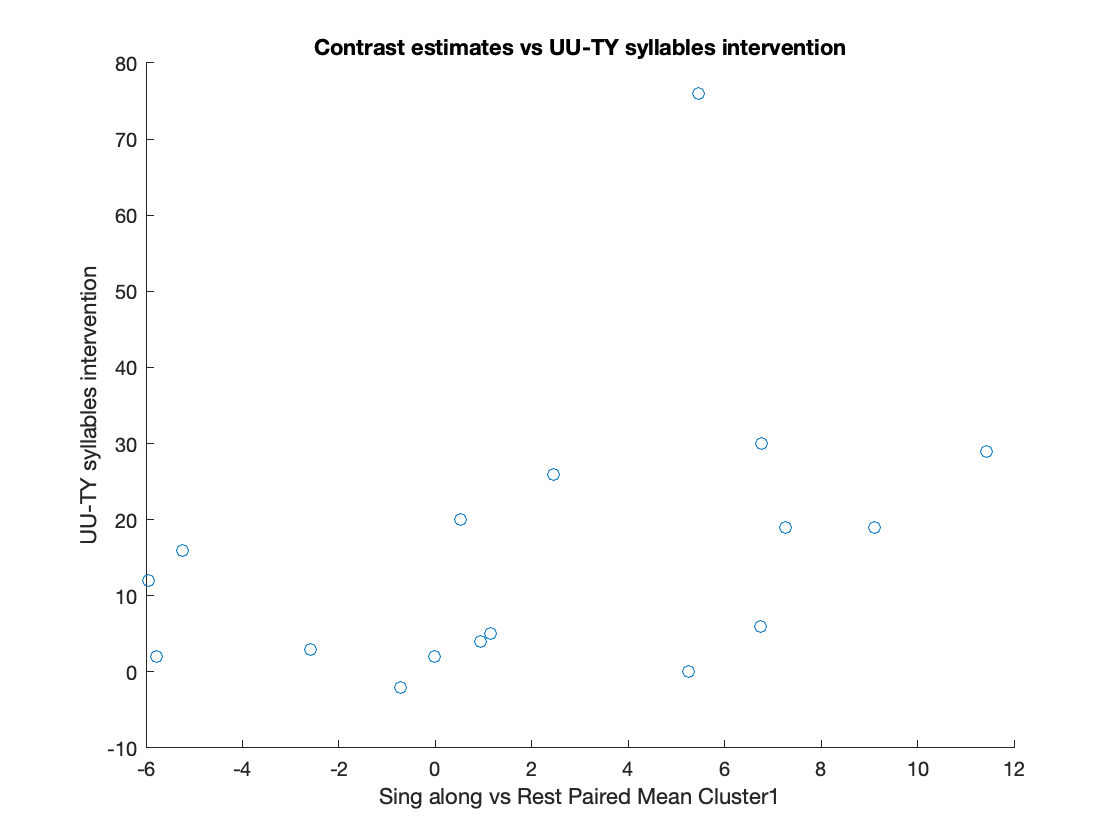

% Get L2 mask indices from FWEc cluster
    mask2=spm_vol(fullfile(mask_path,'flexible factorial/singa_vs_rest_TU_2by3_Age_wo_motion_outliers_wo_14/',mask2name)); %created manually with SPM L2 results
    [M, XYZmm]=spm_read_vols(mask2);
    mask2_idx=find(M~=0);
    mask2_int=mean(M(mask2_idx));%internal check
    
% Get mean cluster intensity for all patients
for i=1:size(filenames_contrast1,1)
    V=spm_vol(fullfile(data_path,contrast1,filenames_contrast1(i).name)); % Get image information
    [Y, XYZmm]=spm_read_vols(V);
    mean_int=mean(Y(mask2_idx));
    [~,name,ext] =fileparts(filenames_contrast1(i).name);
    pa_int_mask2{i,1}=str2num(name(end-1:end)); %Save the patient ID in BIDS
    pa_int_mask2{i,2}=mean_int;% Save mean intensity value for the cluster from all patients
end

%% Get behavioural values from the patients with existing images
ID_BIDS_pat=cell2mat(pa_int_mask2(:,1));
[idx_pat,iall,i] = intersect(ID_BIDS_all,ID_BIDS_pat);
UUTYsyll_int_pat_contrast1f=UUTYsyll_int_all(iall,:);
UUTYsyllerrors_int_pat_contrast1f=UUTYsyllerrors_int_all(iall,:);
UUTYsyllperc_int_pat_contrast1f=UUTYsyllperc_int_all(iall,:);
XXminusYYsyllperc_int_pat_contrast1f=XXminusYYsyllperc_int_all(iall,:);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% BEHAVIORAL VARIABLE #1 %%%
% Remove patients with NaN values in behaviour
if sum(isnan(UUTYsyll_int_pat_contrast1f(:,1)))~=0
    NAN_Index_contrast1f=find(isnan(UUTYsyll_int_pat_contrast1f(:,1)));
    UUTYsyll_int_pat_contrast1f(NAN_Index_contrast1f,:)=[];
    pa_int_mask2_UUTYsyll=cell2mat(pa_int_mask2(:,2));
    pa_int_mask2_UUTYsyll(NAN_Index_contrast1f,:)=[];
end
    
%% Plot Intensity against behaviour for the cluster mean
for p=1:size(1,1)
        y=UUTYsyll_int_pat_contrast1f;
           if exist('pa_int_mask2_UUTYsyll')==1
            x=pa_int_mask2_UUTYsyll;
        else
            x=cell2mat(pa_int_mask2(:,2))
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs UU-TY syllables intervention'), xlabel(['Sing along vs Rest Paired Mean Cluster' num2str(p)]), ylabel ('UU-TY syllables intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_flex_SingavsRest_UUTY_syll_int_mean_cluster' num2str(p) '.jpg'])
        save('UUTY_syll_int_singavsrest_flex_mean_cluster','x','y')
        UUTYsyllint_singavsrest_F=table(x,y);
        writetable(UUTYsyllint_singavsrest_F, 'UUTYsyllint_singavsrest_F_mean_cluster.xlsx')
end


% correlation
[rho_mask2,pval_mask2] = corr(x,y,'Type','Pearson')

rho_mask2 = 0.3999

pval_mask2 = 0.1117

[rho_mask2,pval_mask2] = corr(x,y,'Type','Spearman')

rho_mask2 = 0.5460

pval_mask2 = 0.0234

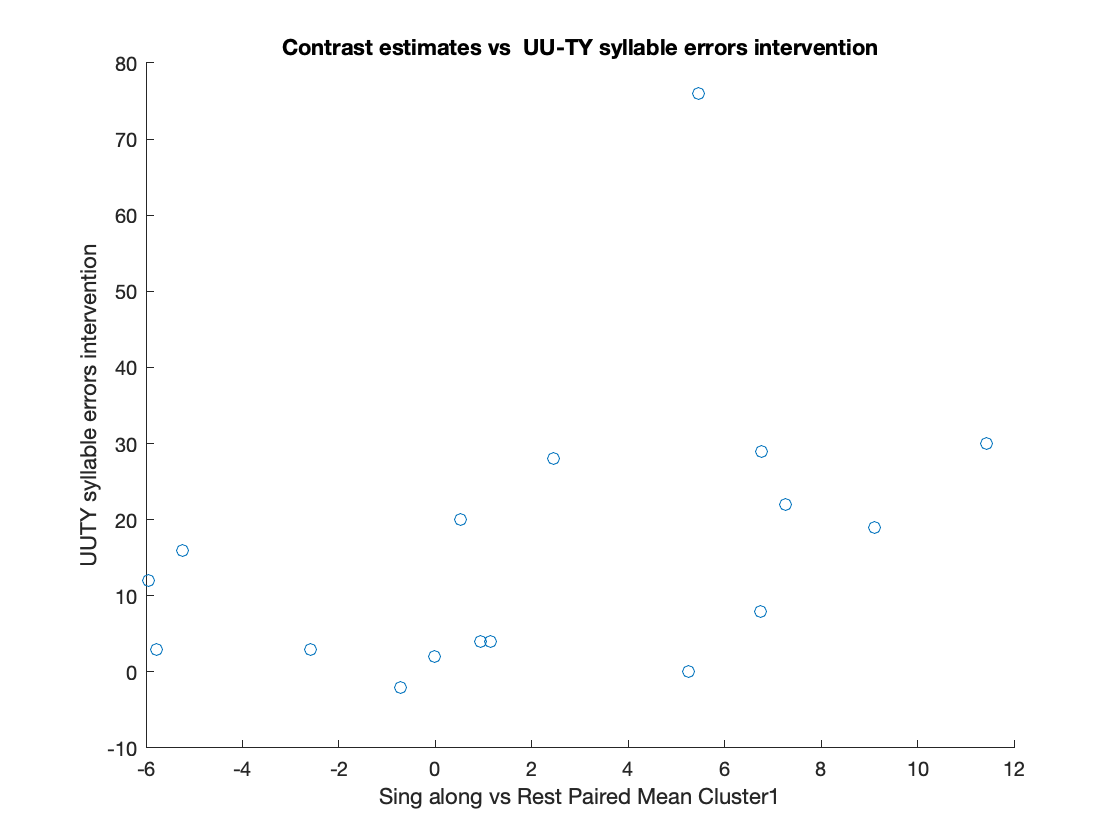

clear x y M mean_int Y V

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% BEHAVIORAL VARIABLE #2 %%%
% Remove patients with NaN values in behaviour
if sum(isnan(UUTYsyllerrors_int_pat_contrast1f(:,1)))~=0
    NAN_Index_contrast1f=find(isnan(UUTYsyllerrors_int_pat_contrast1f(:,1)));
    UUTYsyllerrors_int_pat_contrast1f(NAN_Index_contrast1f,:)=[];
    pa_int_mask2_UUTYsyllerrors=cell2mat(pa_int_mask2(:,2));
    pa_int_mask2_UUTYsyllerrors(NAN_Index_contrast1f,:)=[];
end

%% Plot Intensity against behaviour for the cluster mean
for p=1:size(1,1)
        y=UUTYsyllerrors_int_pat_contrast1f;
           if exist('pa_int_mask2_UUTYsyllerrors')==1
            x=pa_int_mask2_UUTYsyllerrors;
        else
            x=cell2mat(pa_int_mask2(:,2))
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs  UU-TY syllable errors intervention'), xlabel(['Sing along vs Rest Paired Mean Cluster' num2str(p)]), ylabel ('UUTY syllable errors intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_flex_SingavsRest_UUTY_syllable_errors_int_mean_cluster' num2str(p) '.jpg'])
        save('UUTY_syll_errors_int_singavsrest_flex_mean_cluster','x','y')
        UUTYsyllerrorsint_singavsrest_F=table(x,y);
        writetable(UUTYsyllerrorsint_singavsrest_F, 'UUTYsyllerrorsint_singavsrest_F_mean_cluster.xlsx')
end


% correlation
[rho_mask2,pval_mask2] = corr(x,y,'Type','Pearson')

rho_mask2 = 0.4131

pval_mask2 = 0.0994

[rho_mask2,pval_mask2] = corr(x,y,'Type','Spearman')

rho_mask2 = 0.5632

pval_mask2 = 0.0186

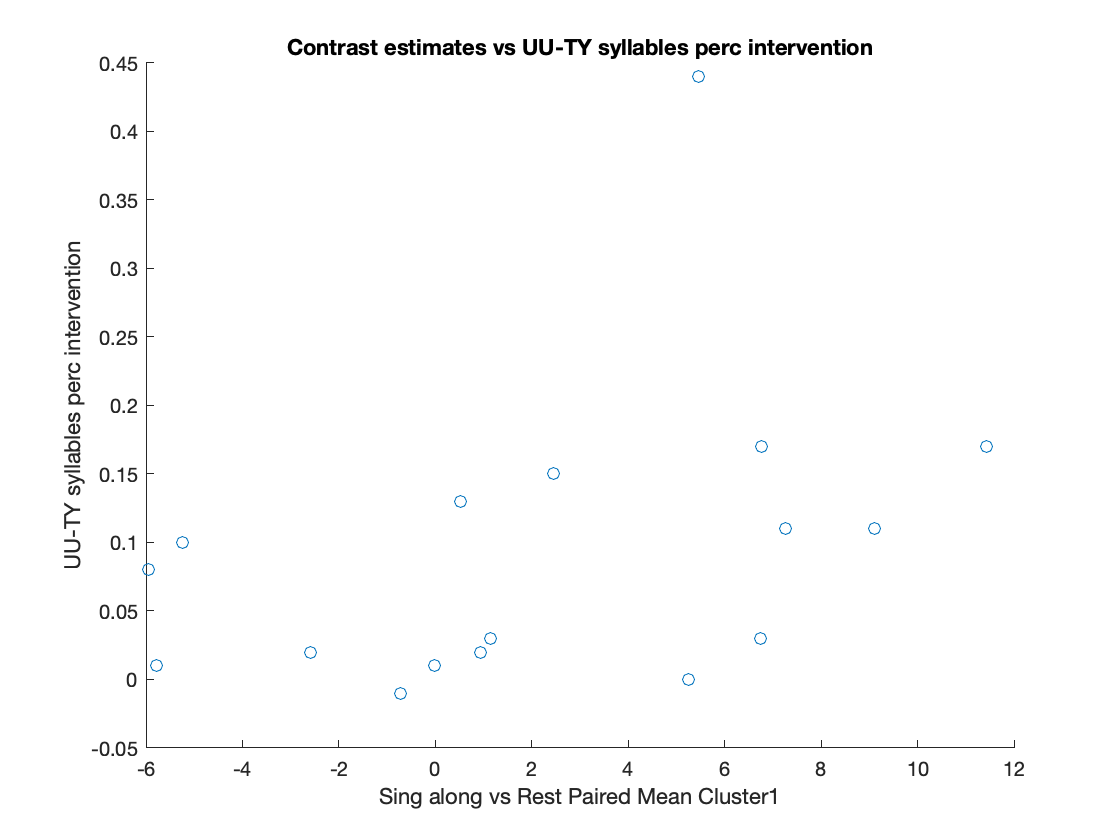

clear x y M mean_int Y V
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% BEHAVIORAL VARIABLE #3 %%%
% Remove patients with NaN values in behaviour
if sum(isnan(UUTYsyllperc_int_pat_contrast1f(:,1)))~=0
    NAN_Index_contrast1f=find(isnan(UUTYsyllperc_int_pat_contrast1f(:,1)));
    UUTYsyllperc_int_pat_contrast1f(NAN_Index_contrast1f,:)=[];
    pa_int_mask2_UUTYsyllperc=cell2mat(pa_int_mask2(:,2));
    pa_int_mask2_UUTYsyllperc(NAN_Index_contrast1f,:)=[];
end
    
%% Plot Intensity against behaviour for the cluster mean
for p=1:size(1,1)
        y=UUTYsyllperc_int_pat_contrast1f;
           if exist('pa_int_mask2_UUTYsyllperc')==1
            x=pa_int_mask2_UUTYsyllperc;
        else
            x=cell2mat(pa_int_mask2(:,2))
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs UU-TY syllables perc intervention'), xlabel(['Sing along vs Rest Paired Mean Cluster' num2str(p)]), ylabel ('UU-TY syllables perc intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_flex_SingavsRest_UUTY_syll_perc_int_mean_cluster' num2str(p) '.jpg'])
        save('UUTY_syll_perc_int_singavsrest_flex_mean_cluster','x','y')
        UUTYsyllpercint_singavsrest_F=table(x,y);
        writetable(UUTYsyllpercint_singavsrest_F, 'UUTYsyllpercint_singavsrest_F_mean_cluster.xlsx')
end


% correlation
[rho_mask2,pval_mask2] = corr(x,y,'Type','Pearson')

rho_mask2 = 0.3792

pval_mask2 = 0.1333

[rho_mask2,pval_mask2] = corr(x,y,'Type','Spearman')

rho_mask2 = 0.5409

pval_mask2 = 0.0250

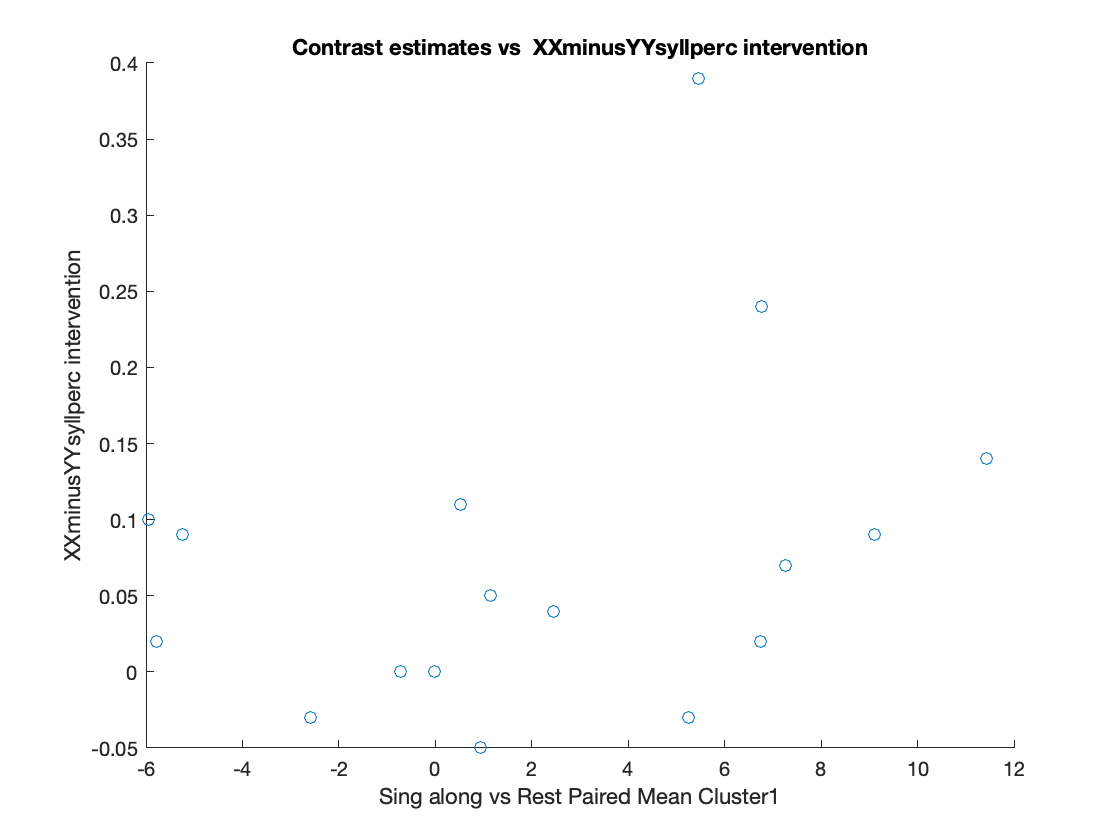

clear x y M mean_int Y V

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% BEHAVIORAL VARIABLE #4 %%%
% Remove patients with NaN values in behaviour
if sum(isnan(XXminusYYsyllperc_int_pat_contrast1f(:,1)))~=0
    NAN_Index_contrast1f=find(isnan(XXminusYYsyllperc_int_pat_contrast1f(:,1)));
    XXminusYYsyllperc_int_pat_contrast1f(NAN_Index_contrast1f,:)=[];
    pa_int_mask2_XXminusYYsyllperc=cell2mat(pa_int_mask2(:,2));
    pa_int_mask2_XXminusYYsyllperc(NAN_Index_contrast1f,:)=[];
end

%% Plot Intensity against behaviour for the cluster mean
for p=1:size(1,1)
        y=XXminusYYsyllperc_int_pat_contrast1f;
           if exist('pa_int_mask2_XXminusYYsyllperc')==1
            x=pa_int_mask2_XXminusYYsyllperc;
        else
            x=cell2mat(pa_int_mask2(:,2))
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs  XXminusYYsyllperc intervention'), xlabel(['Sing along vs Rest Paired Mean Cluster' num2str(p)]), ylabel ('XXminusYYsyllperc intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_flex_SingavsRest_XXminusYYsyllperc_int_mean_cluster' num2str(p) '.jpg'])
        save('XXminusYYsyllpercint_singavsrest_flex_mean_cluster','x','y')
        XXminusYYsyllpercint_singavsrest_F=table(x,y);
        writetable(XXminusYYsyllpercint_singavsrest_F, 'XXminusYYsyllpercint_singavsrest_F_mean_cluster.xlsx')
end


% correlation
[rho_mask2,pval_mask2] = corr(x,y,'Type','Pearson')

rho_mask2 = 0.3274

pval_mask2 = 0.1995

[rho_mask2,pval_mask2] = corr(x,y,'Type','Spearman')

rho_mask2 = 0.3415

pval_mask2 = 0.1797

clear x y M mean_int Y V

  


## Contrast 2: Paired T test Tydyy-Uulaa Sing along vs Sing mem

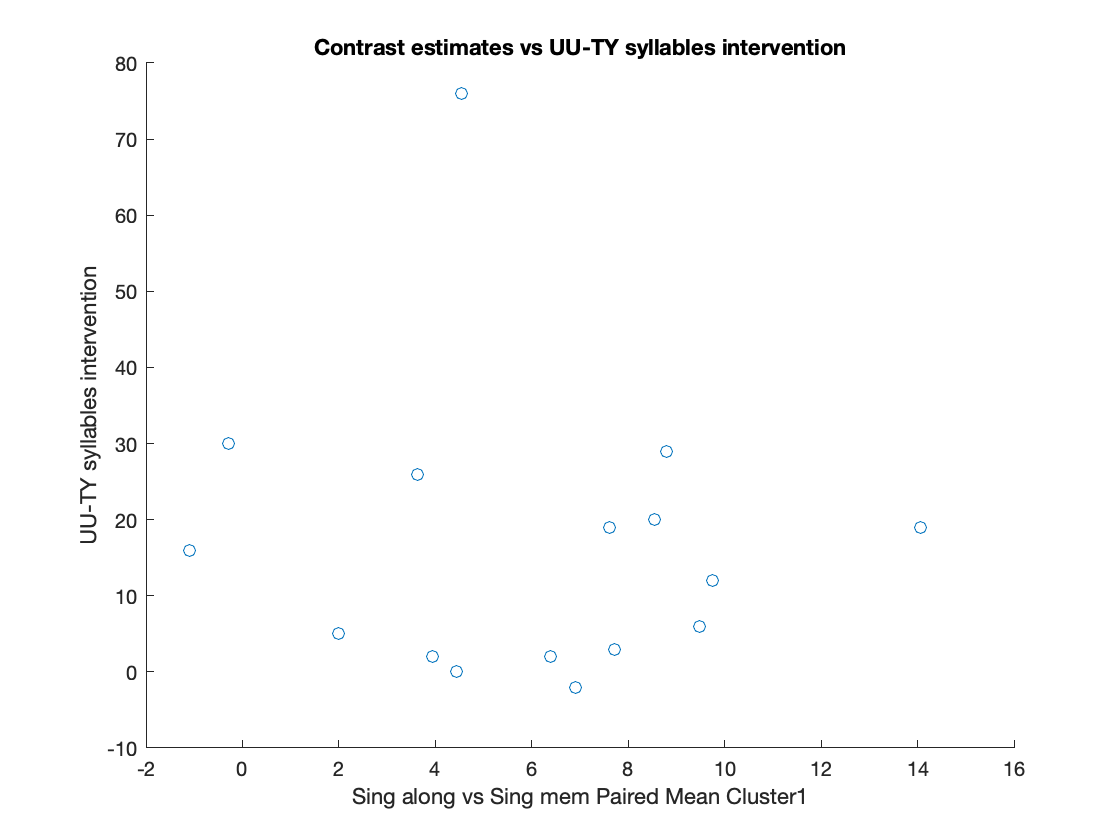

% Get the image filenames
filenames_contrast2= dir(fullfile(data_path,contrast2));
filenames_contrast2(ismember({filenames_contrast2.name},{'.','..'}))=[];

% Get L2 mask indices from FWEc cluster
    mask3=spm_vol(fullfile(mask_path,'paired T test/singa_vs_singm_TU_Age_TIV_wo_motion_outliers_wo_14',mask3name)); %created manually with SPM L2 results
    [M, XYZmm]=spm_read_vols(mask3);
    mask3_idx=find(M~=0);
    mask3_int=mean(M(mask3_idx));%internal check
    
% Get mean cluster intensity for all patients
for i=1:size(filenames_contrast2,1)
    V=spm_vol(fullfile(data_path,contrast2,filenames_contrast2(i).name)); % Get image information
    [Y, XYZmm]=spm_read_vols(V);
    mean_int=mean(Y(mask3_idx));
    [~,name,ext] =fileparts(filenames_contrast2(i).name);
    pa_int_mask3{i,1}=str2num(name(end-1:end)); %Save the patient ID in BIDS
    pa_int_mask3{i,2}=mean_int;% Save mean intensity value for the cluster from all patients
end

%% Get behavioural values from the patients with existing images
ID_BIDS_pat=cell2mat(pa_int_mask3(:,1));
[idx_pat,iall,i] = intersect(ID_BIDS_all,ID_BIDS_pat);
UUTYsyll_int_pat_contrast2=UUTYsyll_int_all(iall,:);
UUTYsyllerrors_int_pat_contrast2=UUTYsyllerrors_int_all(iall,:);
UUTYsyllperc_int_pat_contrast2=UUTYsyllperc_int_all(iall,:);
XXminusYYsyllperc_int_pat_contrast2=XXminusYYsyllperc_int_all(iall,:);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% BEHAVIORAL VARIABLE #1 %%%
% Remove patients with NaN values in behaviour
if sum(isnan(UUTYsyll_int_pat_contrast2(:,1)))~=0
    NAN_Index_contrast2=find(isnan(UUTYsyll_int_pat_contrast2(:,1)));
    UUTYsyll_int_pat_contrast2(NAN_Index_contrast2,:)=[];
    pa_int_mask3_UUTYsyll=cell2mat(pa_int_mask3(:,2));
    pa_int_mask3_UUTYsyll(NAN_Index_contrast2,:)=[];
end
%% Plot Intensity against behaviour for the cluster mean
for p=1:size(mask3,1)
        y=UUTYsyll_int_pat_contrast2;
           if exist('pa_int_mask3_UUTYsyll')==1
            x=pa_int_mask3_UUTYsyll;
        else
            x=cell2mat(pa_int_mask3(:,2))
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs UU-TY syllables intervention'), xlabel(['Sing along vs Sing mem Paired Mean Cluster' num2str(p)]), ylabel ('UU-TY syllables intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_PairedT_SingavsSingm_UUTY_syll_int_T_mean_cluster' num2str(p) '.jpg'])
        save('UUTY_syll_int_singavssingm_mean_cluster','x','y')
        UUTYsyllint_singavssingm_T=table(x,y);
        writetable(UUTYsyllint_singavssingm_T, 'UUTYsyllint_singavssingm_T_mean_cluster.xlsx')
end


% Pearson correlation
[rho_mask3,pval_mask3] = corr(x,y,'Type','Pearson')

rho_mask3 = -0.1054

pval_mask3 = 0.6977

[rho_mask3,pval_mask3] = corr(x,y,'Type','Spearman')

rho_mask3 = 0.0103

pval_mask3 = 0.9698

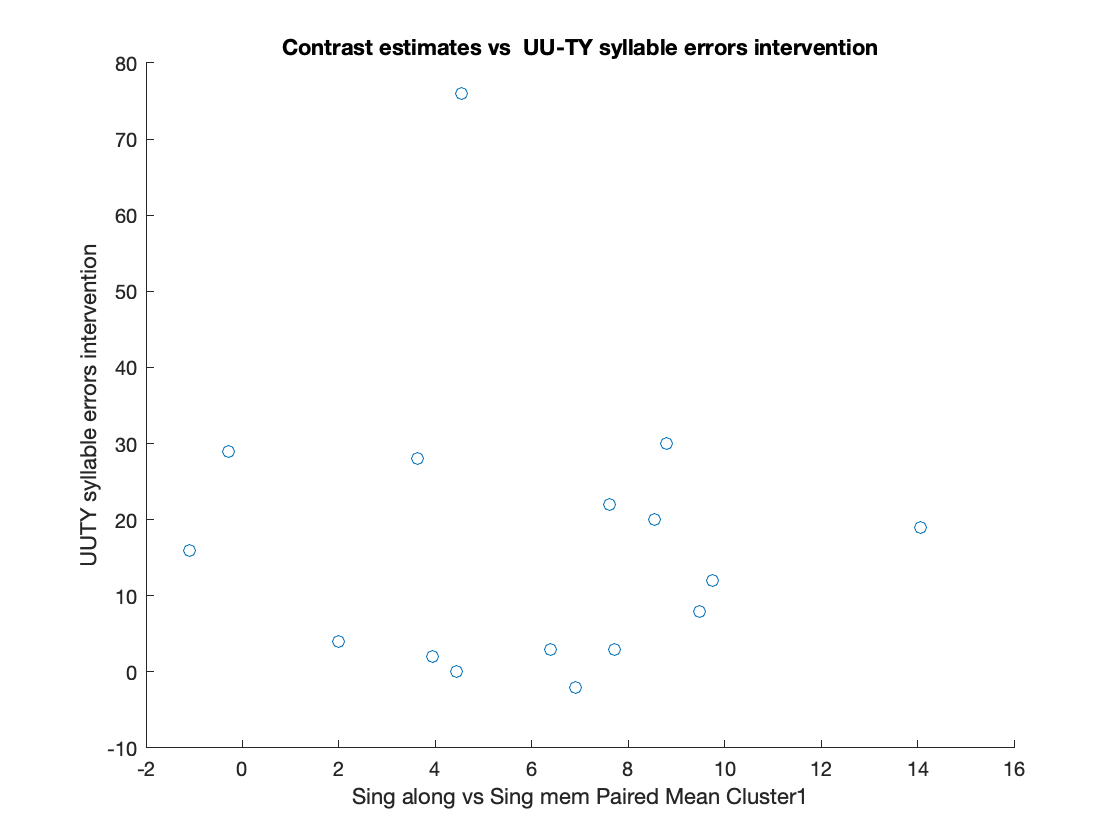


clear x y M mean_int Y V

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% BEHAVIORAL VARIABLE #2 %%%
% Remove patients with NaN values in behaviour
if sum(isnan(UUTYsyllerrors_int_pat_contrast2(:,1)))~=0
    NAN_Index_contrast2=find(isnan(UUTYsyllerrors_int_pat_contrast2(:,1)));
    UUTYsyllerrors_int_pat_contrast2(NAN_Index_contrast2,:)=[];
    pa_int_mask3_UUTYsyllerrors=cell2mat(pa_int_mask3(:,2));
    pa_int_mask3_UUTYsyllerrors(NAN_Index_contrast2,:)=[];
end
%% Plot Intensity against behaviour for the cluster mean
for p=1:size(mask2,1)
        y=UUTYsyllerrors_int_pat_contrast2;
           if exist('pa_int_mask3_UUTYsyllerrors')==1
            x=pa_int_mask3_UUTYsyllerrors;
        else
            x=cell2mat(pa_int_mask3(:,2))
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs  UU-TY syllable errors intervention'), xlabel(['Sing along vs Sing mem Paired Mean Cluster' num2str(p)]), ylabel ('UUTY syllable errors intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_PairedT_SingavsSingm_UUTY_syllable_errors_int_T_mean_cluster' num2str(p) '.jpg'])
        save('UUTY_syll_errors_int_singavssingm_mean_cluster','x','y')
        UUTYsyllerrorsint_singavssingm_T=table(x,y);
        writetable(UUTYsyllerrorsint_singavssingm_T, 'UUTYsyllerrorsint_singavssingm_T_mean_cluster.xlsx')
end


% correlation
[rho_mask3,pval_mask3] = corr(x,y,'Type','Pearson')

rho_mask3 = -0.0871

pval_mask3 = 0.7483

[rho_mask3,pval_mask3] = corr(x,y,'Type','Spearman')

rho_mask3 = 0.0280

pval_mask3 = 0.9181

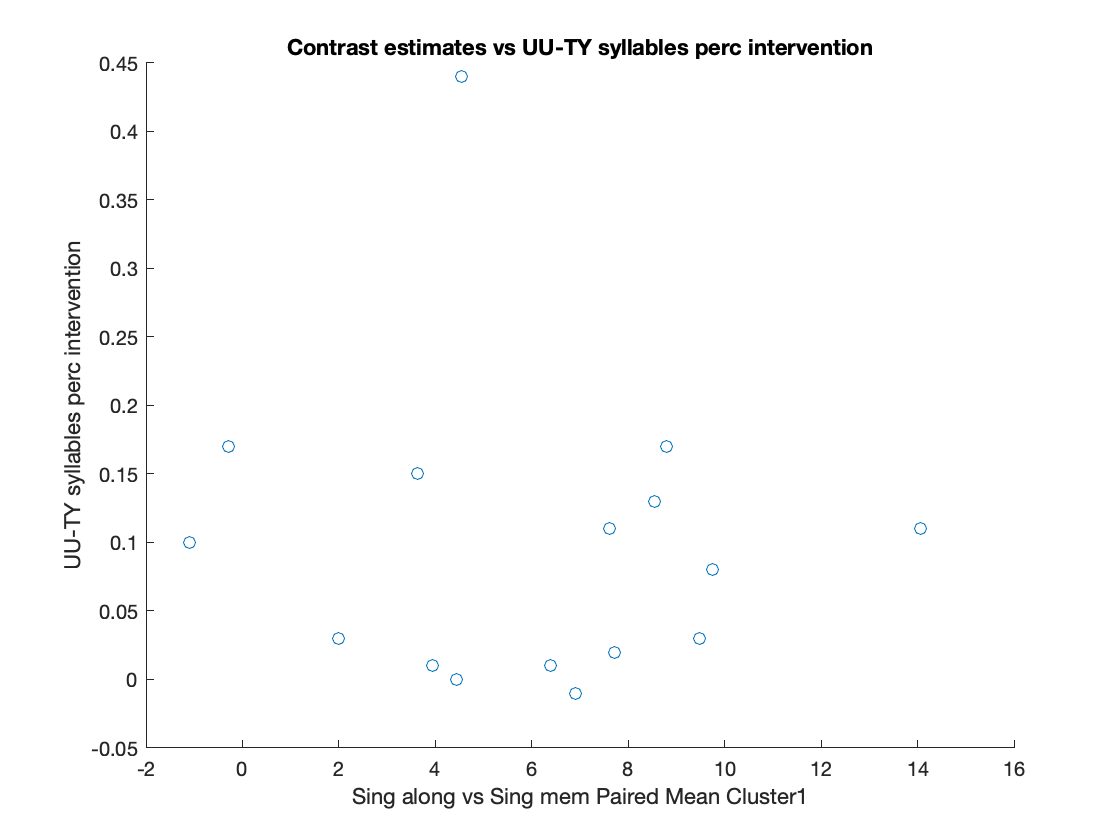


clear x y M mean_int Y V

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% BEHAVIORAL VARIABLE #3 %%%
% Remove patients with NaN values in behaviour
if sum(isnan(UUTYsyllperc_int_pat_contrast2(:,1)))~=0
    NAN_Index_contrast2=find(isnan(UUTYsyllperc_int_pat_contrast2(:,1)));
    UUTYsyllperc_int_pat_contrast2(NAN_Index_contrast2,:)=[];
    pa_int_mask3_UUTYsyllperc=cell2mat(pa_int_mask3(:,2));
    pa_int_mask3_UUTYsyllperc(NAN_Index_contrast2,:)=[];
end
%% Plot Intensity against behaviour for the cluster mean
for p=1:size(mask3,1)
        y=UUTYsyllperc_int_pat_contrast2;
           if exist('pa_int_mask3_UUTYsyllperc')==1
            x=pa_int_mask3_UUTYsyllperc;
        else
            x=cell2mat(pa_int_mask3(:,2))
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs UU-TY syllables perc intervention'), xlabel(['Sing along vs Sing mem Paired Mean Cluster' num2str(p)]), ylabel ('UU-TY syllables perc intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_PairedT_SingavsSingm_UUTY_syll_perc_int_T_mean_cluster' num2str(p) '.jpg'])
        save('UUTY_syll_perc_int_singavssingm_mean_cluster','x','y')
        UUTYsyllpercint_singavssingm_T=table(x,y);
        writetable(UUTYsyllpercint_singavssingm_T, 'UUTYsyllpercint_singavssingm_T_mean_cluster.xlsx')
end


% Pearson correlation
[rho_mask3,pval_mask3] = corr(x,y,'Type','Pearson')

rho_mask3 = -0.0990

pval_mask3 = 0.7152

[rho_mask3,pval_mask3] = corr(x,y,'Type','Spearman')

rho_mask3 = 0.0103

pval_mask3 = 0.9697

UUTYsyllperc_int_pat_contrast2

UUTYsyllperc_int_pat_contrast2 =     0.1700
    0.0800
    0.1300
         0
   -0.0100
    0.1100
    0.0300
    0.4400
    0.1500
    0.0200


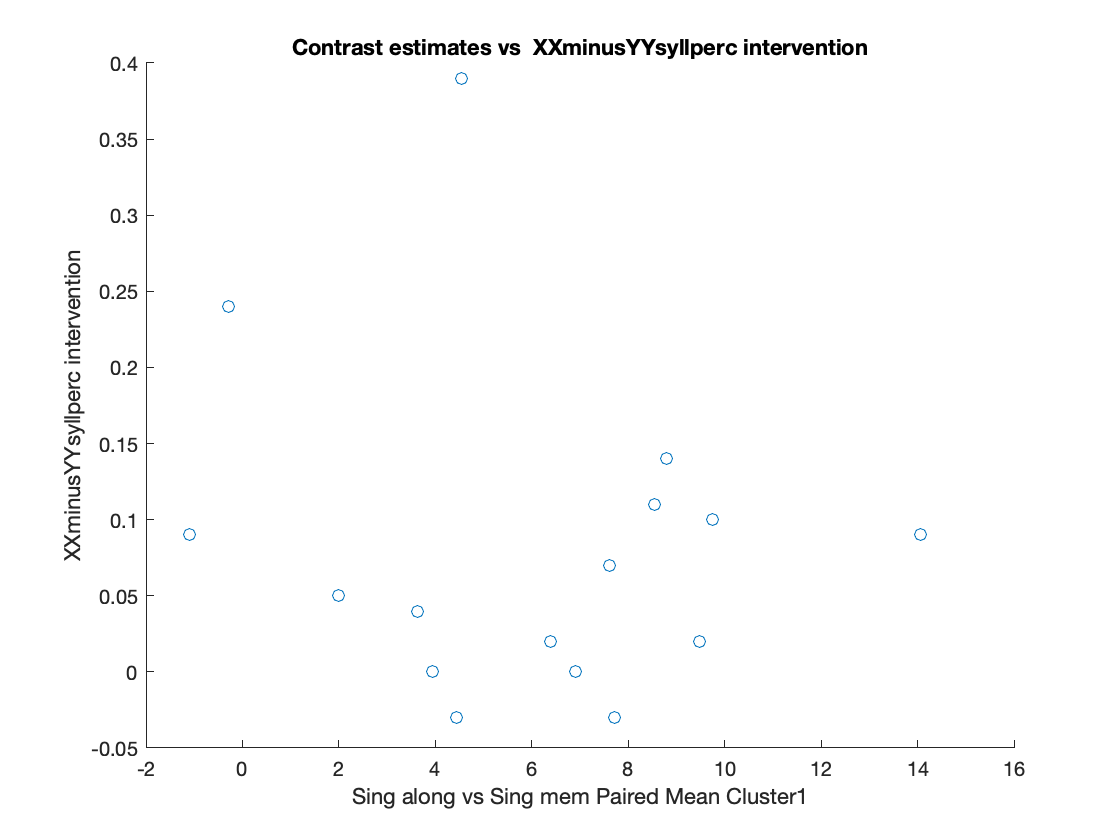

clear x y M mean_int Y V

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% BEHAVIORAL VARIABLE #4 %%%
% Remove patients with NaN values in behaviour
if sum(isnan(XXminusYYsyllperc_int_pat_contrast2(:,1)))~=0
    NAN_Index_contrast2=find(isnan(XXminusYYsyllperc_int_pat_contrast2(:,1)));
    XXminusYYsyllperc_int_pat_contrast2(NAN_Index_contrast2,:)=[];
    pa_int_mask3_XXminusYYsyllperc=cell2mat(pa_int_mask3(:,2));
    pa_int_mask3_XXminusYYsyllperc(NAN_Index_contrast2,:)=[];
end
%% Plot Intensity against behaviour for the cluster mean
for p=1:size(mask2,1)
        y=XXminusYYsyllperc_int_pat_contrast2;
           if exist('pa_int_mask3_XXminusYYsyllperc')==1
            x=pa_int_mask3_XXminusYYsyllperc;
        else
            x=cell2mat(pa_int_mask3(:,2))
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs  XXminusYYsyllperc intervention'), xlabel(['Sing along vs Sing mem Paired Mean Cluster' num2str(p)]), ylabel ('XXminusYYsyllperc intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_PairedT_SingavsSingm_XXminusYYsyllperc_int_T_mean_cluster' num2str(p) '.jpg'])
        save('XXminusYYsyllpercint_singavssingm_mean_cluster','x','y')
        XXminusYYsyllpercint_singavssingm_T=table(x,y);
        writetable(XXminusYYsyllpercint_singavssingm_T, 'XXminusYYsyllpercint_singavssingm_T_mean_cluster.xlsx')
end


% correlation
[rho_mask3,pval_mask3] = corr(x,y,'Type','Pearson')

rho_mask3 = -0.1705

pval_mask3 = 0.5277

[rho_mask3,pval_mask3] = corr(x,y,'Type','Spearman')

rho_mask3 = 0.0590

pval_mask3 = 0.8282


clear x y M mean_int Y V
